# Using Functions and Projectors

## Introduction

In these tutorial files, you will learn how to use the various modules of Swan in order to generate your own FEM and Topology Optimization simulations. In each tutorial, a single building block will be analyzed, with some examples to make it easier. If you have any questions, feel free to create a new issue in the GitHub repository.

In this tutorial, we will learn how to use Functions and Projectors in Swan.

## Functions and projectors

Swan's `Functions` represent mathematical functions. First of all, their domain needs to be defined using a Mesh:

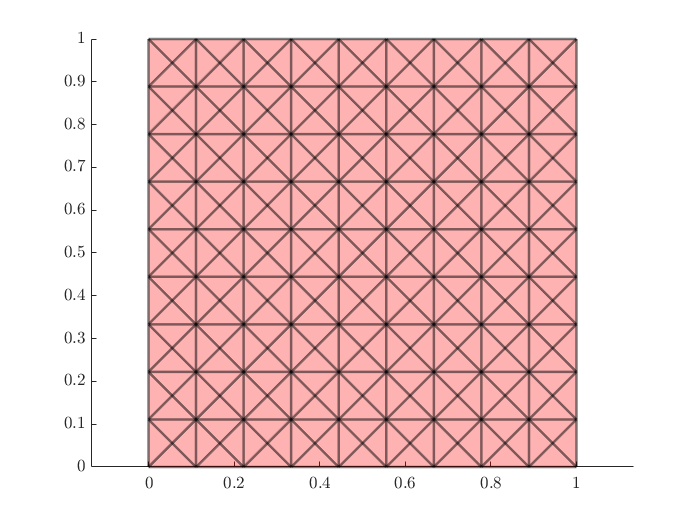

close all;

x1 = linspace(0,1,10);
x2 = linspace(0,1,10);
[xv,yv] = meshgrid(x1,x2);
[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');
sBg.coord  = V(:,1:2);
sBg.connec = F;
mesh = Mesh(sBg);
figure
mesh.plot()

Having created a mesh, we can now dive deeper into the various functions that Swan includes. We can start with AnalyticalFunction, which uses a function handle to determine its value:

sAF.fHandle = @(x) sin(2*pi*x(1,:,:)); % f(x) = sin(2*pi*x)
sAF.ndimf   = 1; % number of dimensions
sAF.mesh    = mesh;
xFun = AnalyticalFunction(sAF);

We can project this function onto various different spaces, including P0, P1, P2 and P3:

p0fun = xFun.project('P0');
p1fun = xFun.project('P1');
p2fun = xFun.project('P2');
p3fun = xFun.project('P3');

These functions have additional useful methods:

- *evaluate(xG)*: returns the values of the functions at the given Gauss points

- *plot()*: plot the function in Matlab

- *print(filename, software)*: print the function to visualize it in GiD or Paraview

## Projected Functions Error

In order to compute the error generated during the projection of the function we can use the Integrator Error class of Swan as it is shown next:

r.mesh = sAF.mesh;
r.quadType = 'ORDER10';
r.type = 'Error';
int = Integrator.create(r);

error_P1 = int.compute(p1fun,xFun)/p1fun.computeL2norm();
error_P2 = int.compute(p2fun,xFun)/p2fun.computeL2norm();
error_P3 = int.compute(p3fun,xFun)/p3fun.computeL2norm();

If this process is repeated for different numbers of elements, the error trend can be studied. First define meshes with different number of elements:

N = [4 8 16 32 64];

for i = length(N)
    x1 = linspace(0,1,N(i));
    x2 = linspace(0,1,N(i));
    [xv,yv] = meshgrid(x1,x2);
    [F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');
    sBg.coord  = V(:,1:2);
    sBg.connec = F;
    m(i) = Mesh(sBg);
end

Not enough input arguments.

Error in Mesh (line 36)
            obj.init(cParams);

Now let's repeat the process of projecting the functions and calculating the error for these meshes:

e_p1 = zeros(size(N));
e_p2 = zeros(size(N));
e_p3 = zeros(size(N));

for i = 1:length(N)
    
    sAf.mesh = m(i);
    xFun = AnalyticalFunction(sAF);
    
    p1fun = xFun.project('P1');
    p2fun = xFun.project('P2');
    p3fun = xFun.project('P3');
    
    r.mesh = sAF.mesh;
    int = Integrator.create(r);
    
    e_p1(i) = int.compute(p1fun,xFun)/p1fun.computeL2norm();
    e_p2(i) = int.compute(p2fun,xFun)/p2fun.computeL2norm();
    e_p3(i) = int.compute(p3fun,xFun)/p3fun.computeL2norm();
end

Finally, plot the results:

figure()
loglog(1./N,e_p1,'-x')
hold on
loglog(1./N,e_p2,'-x')
loglog(1./N,e_p3,'-x')
loglog(1./N,1./N.^2,'-x')
loglog(1./N,1./N.^4,'-x')
loglog(1./N,1./N.^6,'-x')
grid on
legend('P1 error','P2 error','P3 error','$h^2$','$h^4$','$h^6$','Location','best')
xlabel('h')
ylabel('Error')
title('P1, P2 and P3 Projections Error')